# Lysosome Stats

Use this script to generate the figures presented in the manuscript. 

Requires the following variables to be loaded:

## Load Variables

Change directory to the Lysosome Analysis Folder 

clearvars -except paths proj
close all
clc
[VL, idT, cellT, dyingT,lysT] = loadProjectTables(paths)
idT = sortrows(idT,["Type", "Health"])

### Group Stats by cell

Calculate the stats of the lysosomes per cells. 

s = groupsummary(lysT,"Cell",["sum","median","mean","std","max","min"],"Volume");
s.Properties.VariableNames = {'Object',...
    'LysCount', 'LysTotalVol','LysMedianVol','LysMeanVol','LysStdVol','LysMaxVol','LysMinVol'}

- **LysCount**: total number of lysosomes found in a cell

- **LysTotalVolume**: summed volume of all lysosomes found in a cell

- **LysMedianVol**: median volume of lysosomes found in a cell

- **LysTraceMedian**: The median cross-sectional area of a lysosome in a given cell

## Visualization

### Plot: Lysosome Count and Median Lysosome Volume

likely a function of volume

figure(Visible="on",WindowStyle="docked",Color='white')

tiledlayout("horizontal")


% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;

Error using  .  (line 229)
Unrecognized table variable name 'PlotSort'.

y = cellT.LysCount;

y2 = cellT.LysMedianVol;
y2_label = ("Median Lys Vol")

% y2 = cellT.LysCellRatio;

nexttile
hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
% boxchart(g,y,GroupByColor=g,Notch="off")


ylabel("Lysosome Count")
xlabel("")
grid on


nexttile

swarmchart(g,y2, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
hold on
boxchart(g,y2,"BoxFaceColor","#0072BD",Notch="off")

xlabel("cell type")
grid on

ylabel(y2_label)

## Volume Analysis

### Cell stats

cell_stats = groupsummary(cellT,"PlotSort",["min" "max"],"Volume")

stats = 5×4 table
    PlotSort    GroupCount    min_Volume    max_Volume
    ________    __________    __________    __________

      IV            4           323.42        650.55  
      III           7           232.58        514.78  
      II            5           468.53        808.45  
      I             9           378.07        1136.9  
      d             8           360.47        1136.5  


### Visualize

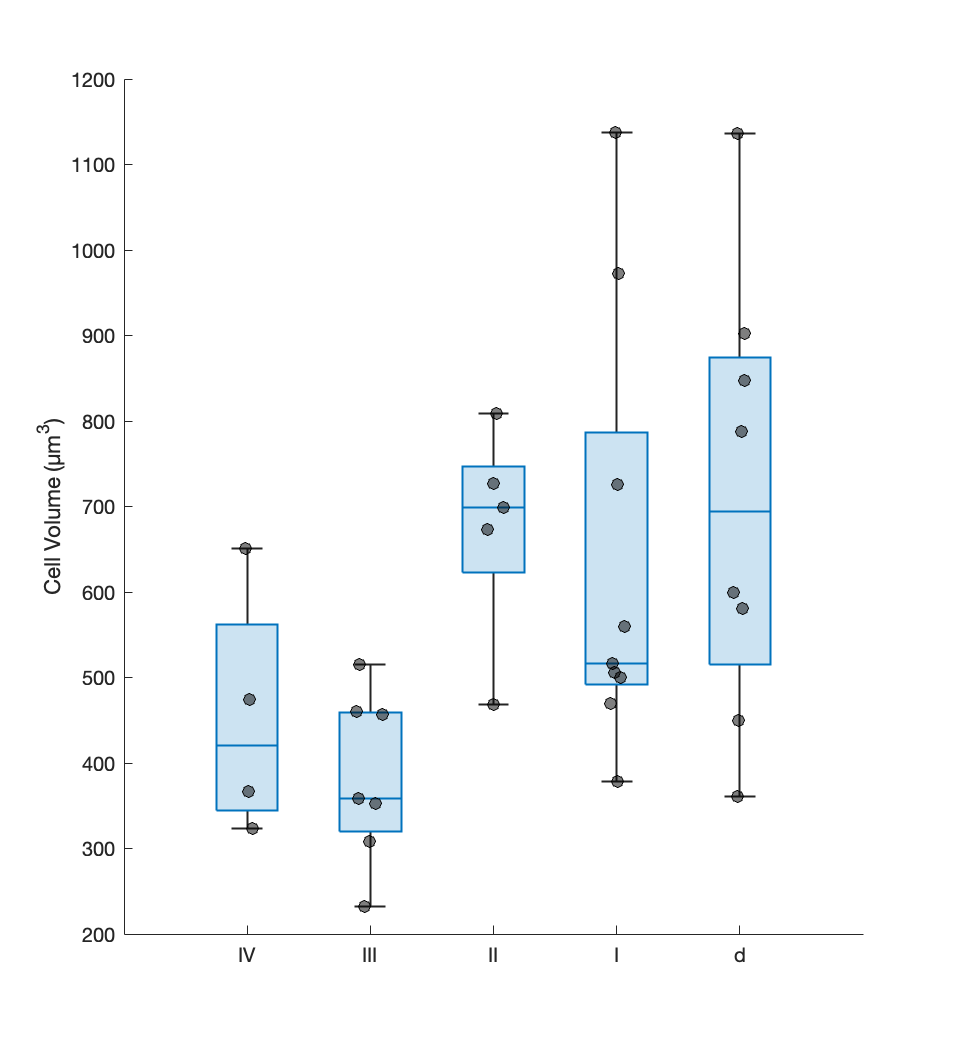

mmfig;

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.Volume;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel('Cell Volume (µm^3)')

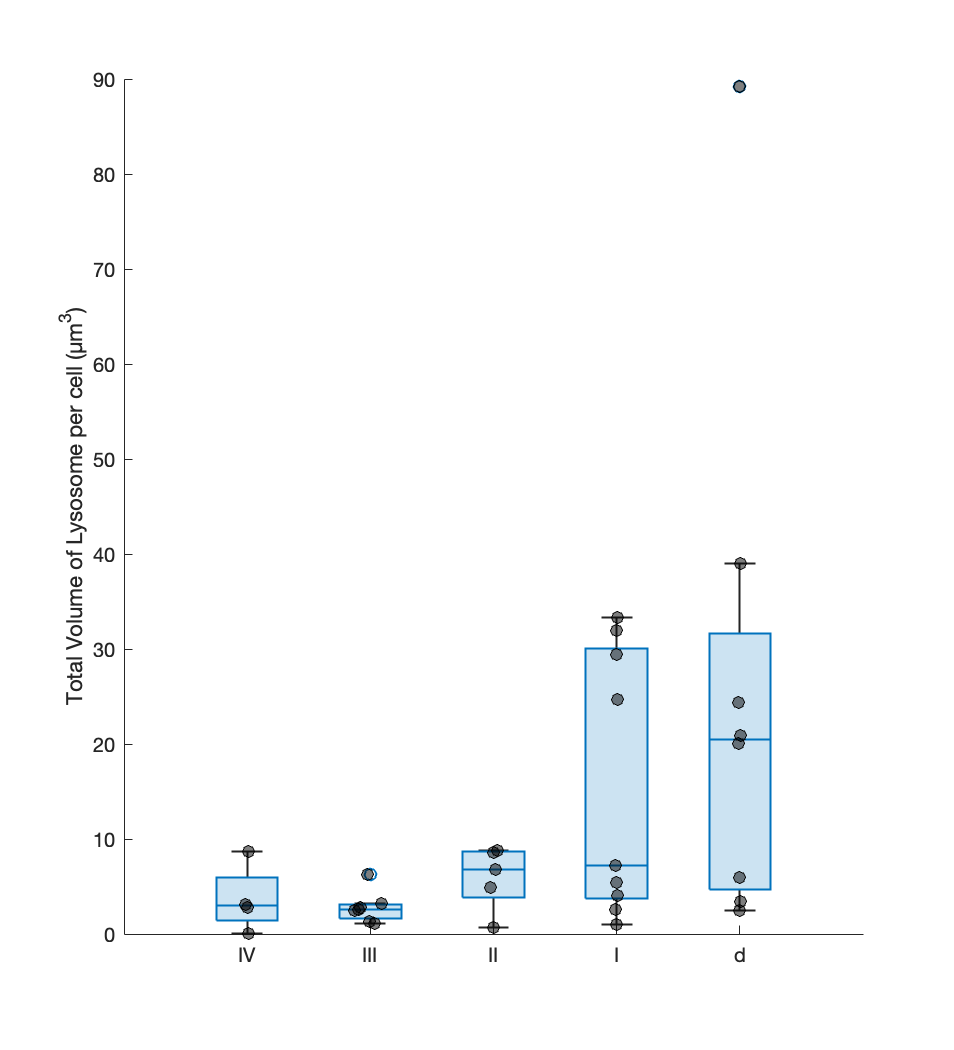

mmfig;

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.LysTotalVol;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Total Volume of Lysosome per cell (µm^3)")